Variables:

    experience_level: 2048×1 categorical

        Values:

            Entry-level            266  
            Executive               67  
            Mid-level              608  
            Senior                1106  
            experience_level         1  

    employment_type: 2048×1 categorical

        Values:

            Contract                1  
            Freelance               1  
            Full-time            2045  
            employment_type         1  

    salary_in_usd: 2048×1 double

        Values:

            Min             17598     
            Median          1.4e+05   
            Max             4.48e+05  
            NumMissing      1         

    company_location: 2048×1 categorical

        Values:

            Argentina                      2  
            Australia                     16  
            Austria                        4  
            Bosnia and Herze

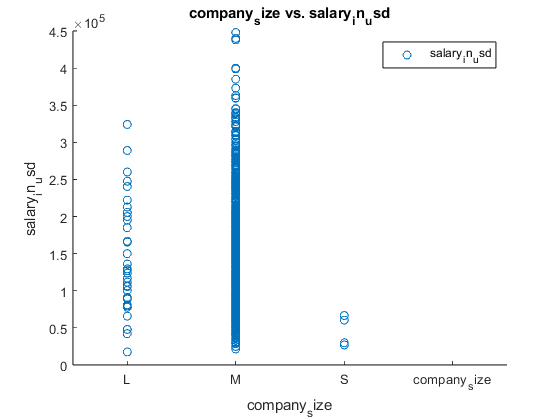

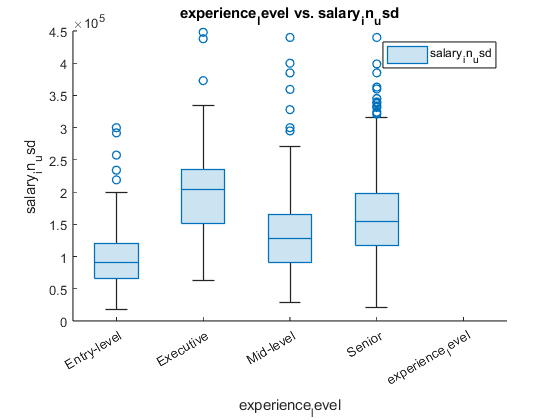

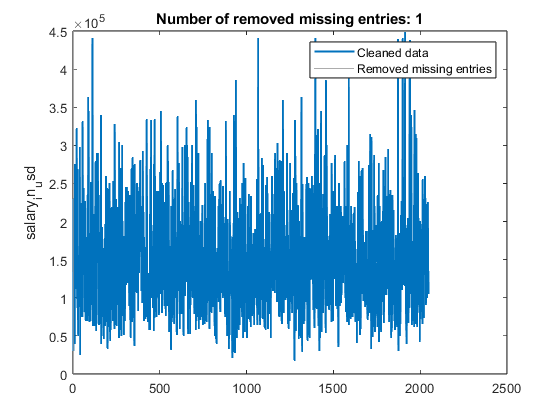

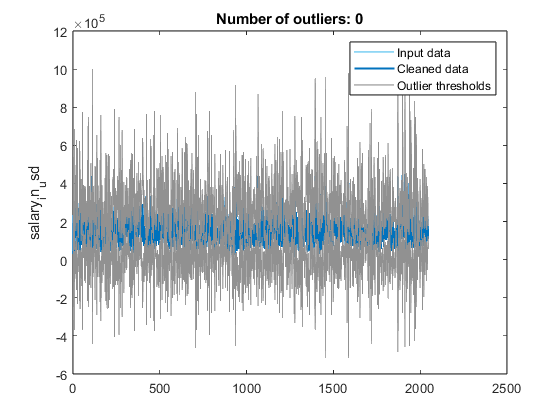

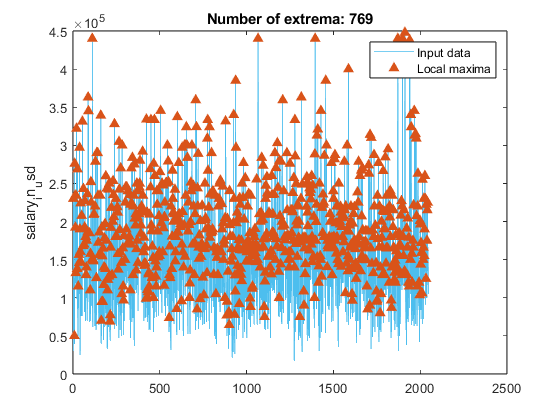

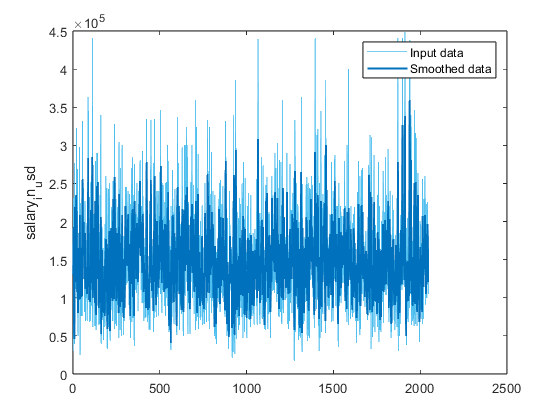

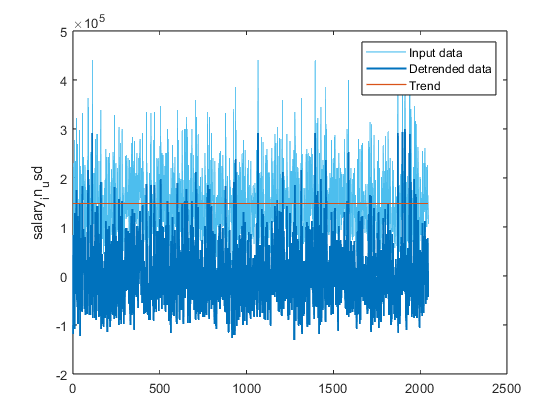

summary(jobs2024final)

% Create scatter of jobs2024final.company_size and jobs2024final.salary_in_usd
s = scatter(jobs2024final.company_size,jobs2024final.salary_in_usd,'DisplayName','salary_in_usd');

% Add xlabel, ylabel, title, and legend
xlabel('company_size')
ylabel('salary_in_usd')
title('company_size vs. salary_in_usd')
legend

% Create boxchart of jobs2024final.experience_level and jobs2024final.salary_in_usd
h = boxchart(jobs2024final.experience_level,jobs2024final.salary_in_usd,'DisplayName','salary_in_usd');

% Add xlabel, ylabel, title, and legend
xlabel('experience_level')
ylabel('salary_in_usd')
title('experience_level vs. salary_in_usd')
legend

% Remove missing data
[newTable,missingIndices] = rmmissing(jobs2024final,...
    "DataVariables","salary_in_usd");

% Display results
clf
plot(find(~missingIndices),newTable.salary_in_usd,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")
hold on

% Plot removed missing entries
x = repelem(find(missingIndices),3);
y = repmat([ylim(gca) missing]',nnz(missingIndices),1);
plot(x,y,"Color",[145 145 145]/255,"DisplayName","Removed missing entries")
title("Number of removed missing entries: " + nnz(missingIndices))

hold off
legend
ylabel("salary_in_usd")
clear x y

% Remove outliers
[newTable2,outlierIndices] = rmoutliers(newTable,"movmedian",2,...
    "DataVariables","salary_in_usd");

% Display results
clf
plot(newTable.salary_in_usd,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(find(~outlierIndices),newTable2.salary_in_usd,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices),newTable.salary_in_usd(outlierIndices),"x",...
    "Color",[217 83 25]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices))

% Additional outlier computations for plot
[~,thresholdLow,thresholdHigh] = isoutlier(newTable.salary_in_usd,"movmedian",2);

% Plot outlier thresholds
plot([(1:numel(newTable.salary_in_usd))'; missing; (1:numel(newTable.salary_in_usd))'],...
    [thresholdHigh(:); missing; thresholdLow(:)],"Color",[145 145 145]/255,...
    "DisplayName","Outlier thresholds")

hold off
legend
ylabel("salary_in_usd")
clear thresholdLow thresholdHigh

% Find local maxima
maxIndices = islocalmax(newTable2,"DataVariables","salary_in_usd");

% Display results
clf
plot(newTable2.salary_in_usd,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on

% Plot local maxima
plot(find(maxIndices(:,3)),newTable2.salary_in_usd(maxIndices(:,3)),"^",...
    "Color",[217 83 25]/255,"MarkerFaceColor",[217 83 25]/255,...
    "DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices(:,3)))
hold off
legend
ylabel("salary_in_usd")

% Smooth input data
newTable3 = smoothdata(newTable2,"movmean","SmoothingFactor",0.5,...
    "DataVariables","salary_in_usd");

% Display results
clf
plot(newTable2.salary_in_usd,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(newTable3.salary_in_usd,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
ylabel("salary_in_usd")

idx = 0.2

idx = 0.2000

finaldata = movevars(newTable3,"salary_in_usd", "After","job_category")

finaldata = 2047×6 table
    experience_level    employment_type    company_location    company_size             job_category             salary_in_usd
    ________________    _______________    ________________    ____________    ______________________________    _____________

      Entry-level          Freelance        United Kingdom          M          Data Science and Research             1.3e+05  
      Executive            Full-time        United States           M          BI and Visualization               1.4563e+05  
      Executive            Full-time        United States           M          BI and Visualization                1.927e+05  
      Senior               Full-time        Canada                  M          Data Architecture and Modeling     1.4677e+05  
      Se

hpartition = cvpartition(length(finaldata.salary_in_usd),'HoldOut',idx)

hpartition = Hold-out cross validation partition
   NumObservations: 2047
       NumTestSets: 1
         TrainSize: 1638
          TestSize: 409

idxTrain = training(hpartition);
trainData = finaldata(idxTrain,:)

trainData = 1638×6 table
    experience_level    employment_type    company_location    company_size             job_category             salary_in_usd
    ________________    _______________    ________________    ____________    ______________________________    _____________

      Entry-level          Freelance        United Kingdom          M          Data Science and Research             1.3e+05  
      Executive            Full-time        United States           M          BI and Visualization               1.4563e+05  
      Executive            Full-time        United States           M          BI and Visualization                1.927e+05  
      Senior               Full-time        Canada                  M          Data Architecture and Modeling     1.4677e+05  
      Se

idxTest= test(hpartition);
testData=finaldata(idxTest,:)

testData = 409×6 table
    experience_level    employment_type    company_location    company_size           job_category            salary_in_usd
    ________________    _______________    ________________    ____________    ___________________________    _____________

      Mid-level            Full-time        United Kingdom          M          Data Science and Research            65931  
      Senior               Full-time        United States           M          Data Engineering                1.5467e+05  
      Senior               Full-time        United States           M          Data Engineering                2.1933e+05  
      Entry-level          Full-time        United States           M          Leadership and Management       1.5933e+05  
      Senior               F